# Entropic Causal Inference for Neurological Applications

## Entropic Regression and Kuramoto Model  

### User-defined variables and parallel computations options

clearvars; close all; clc;

rng('default'); rng(8);   % For reproducibility

Network = 'DTI'; % The network to be used.
                 % other choices are 'ER' and 'Comm'. See Networks section
                 % for more details

N = 83;          % Number of nodes
M = 1000;        % sample size

useParallel = true;     % Use parallel computations.
nCores      = N;        % Number of cores to use, the default will use the smaller of 
                        % the maximum number of cores available and the network size.
                        % Check your computer and select number of cores to use.
                        


### Solving the forward model and obtaining the observations

In the popular version of the Kuramoto model, each of the oscillators is considered to have its own intrinsic natureral frequency $\omega_i$ ,  and initial phase angle $\theta_i$. Then, for $N$ oscillators, the governing equations of Kuramoto model is given by:


$$\dot{\theta}_i =  \omega_i + \frac{K}{N} \sum_{j=1}^{N} \sin(\theta_j - \theta_i )$$


Which is the general form that assums all oscillators to be coupled to each others (all-to-all network). In the case that the oscillators are coupled according to the adjacency matrix $A$, the governing equation become:

$\dot{\theta}_i =  \omega_i + \frac{K}{N} \sum_{j=1}^{N} A_{ij} \sin(\theta_j - \theta_i )$.

Here, we will consider different approches for constructing the matrix $A$. Please refer to the text for more details.

### 
$$\text { Erd\H{o}s-Rényi Graph: } G(n,p)$$



$$\text{The Erd\H{o}s-R\'{e}nyi19 (ER) graph, is the classical random graph wherein edges are assigned at random with probability} p.$$


$\text{That each edge has a probability } p \text{ to be 1 and a probability } 1-p \text{ to be } 0.$  ($\text{Excluding the self connection}$)

p = 0.225;
Aer = (rand(N)<p) .* (~eye(N));

### $\text{Community Graph}$:

We In this example, we stick to the structure we presented in our paper for the community graph. We chose 80 nodes with 5 communities of 16 nodes each. Each node has some number of intra-community connections and inter-community connections. We chose 13 intra-community connections and 5 inter-community connections. To generate these graphs efficiently we only guaranty that these are the maximum number of edges and choose the edges with one forward pass. 13 and 5 were chosen so that the community graph has a maximum sparsity of 0.225 as close as possible to the DTI graph. 


numInterConnections = 5;
numIntraConnections = 13;
communitySize = 16;
numOfCommunities = 5;

interP = (numInterConnections*communitySize)/(communitySize*(N-communitySize));
intraP = numIntraConnections/communitySize;

BLK = cell(1,numOfCommunities);
for i=1:numOfCommunities
    BLK{i} = rand(communitySize)<intraP;
end

Ac = double(~~(blkdiag(BLK{:}) + (rand(numOfCommunities*communitySize)<interP)));



### 
$$\text{Diffusion Tensor Imaging (DTI)}$$


The DTI is a real network of the anatomical brain regions which has been reconstructed from diffusion tensor imaging (DTI) data.

The coupling matrix is already stored in the file DTI.mat.

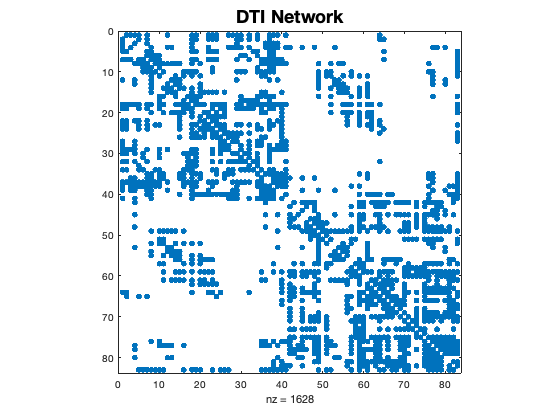

Adti = load('DTI','A').A;

figure

% Here, we check for the choosen network
switch Network
    case 'DTI'
        A = Adti;
        N = length(A); % DTI size is fixed to 83 nodes, so, 
                       % we update N in case it is different.
        figure;
        spy(Adti)
        title('DTI Network','FontSize',18)
    case 'ER'
        A = Aer;
        figure;
        spy(Aer)
        title('Erdos-Renyi Graph','FontSize',18)
    case 'Comm'
        A = Ac;
        figure;
        spy(Ac)
        title('Community Graph','FontSize',18)
end % Now, the matrix A is the network adjacency matrix.
drawnow

**Initial Conditions**

% Initial conditions
K  = (2*sqrt(2*pi)/pi)*(1/eigs(double(A),1))*N;  % Kuramoto Critical Coupling

dt = 0.125; % Time step

Th0 = mod(2*pi*randn(N,1),2*pi);     %theta Initial condition
w   = mod(2*pi*randn(N,1),2*pi);     %natural frequency initial condition



**Kuramoto ODE Function**

dTheta = @(~,theta) w + (K/N)*sum(A.*sin(theta'-theta),2); % Kuramoto ODE model


**Data Sampling and Derivative Estimation**

% Solving the forward model, and collecting the observations
[~,Th] = ode45(dTheta, 0:dt:M*dt, Th0); 

% Find the derivative with the forward difference 
Thdot = (Th(2:end,:)-Th(1:end-1,:))./dt;
Th(end,:) = [];

Now, the evolution of the angle $\theta$ through time for all oscillators is stored in the matrix Th, and the estimated derivative is stored in Thdot.

These are the only matrices that will be used in the entropic regression to recover the coupling structure.

## Calling Entropic Regression

Depending on the size of the network, computaions can be expensive. So, we provide the option to use parallel computations. See user defined options above for details. 

tic              % Start timer.
C   = zeros(N);  % Initialize the matrix to store the relevence weight of each edge.
tol = zeros(N,1);% Initialize the vector to store the estimated tolerence.

parfor (i=1:N, double(useParallel*nCores))
    [C(i,:), tol(i)] = erfit_Kuramoto(Thdot(:,i),Th, i);
end
% The i^th row in the matrix C, will have weights representing 
% the strength that other nodes influence the i^th node.
time = toc;
disp(['Run time = ' num2str(time/60,'%.1f') ' minutes'])

Run time = 60.5 minutes


## Results and Performance Measures

In the following we show the results of entropic regression network recovery. As a performance measures, we considered to find the following:

**1 ) Receiver operating characteristic (ROC) curve**: A receiver operating characteristic curve, or ROC curve, is a graphical plot that illustrates a binary classifier system diagnostic ability as its discrimination threshold is varied. The ROC curve is created by plotting the true positive rate (TPR) against the false positive rate (FPR) at various threshold settings. The TPR, and FPR are defined as the following: 


$$TPR = \frac{TP}{TP + FN}$$
 

 $FPR = \frac{FP}{FP+TN}$.

where $TP$ is the number of true positives, $FP$ is the false positive, $TN$ is the true negative, and $FN$ is the number of false negative.

2 ) **Area Under the Curve (AUC):** It is a scale-invariant and classification-threshold-invariant measure. It measures the quality of the model's predictions irrespective of what classification threshold is chosen. In normalized ROC, the AUC ranges in value from 0 to 1. A model whose predictions are 100% wrong has an AUC of 0.0, and ***AUC = 1 represents a perfect classifier*** whose predictions are 100% correct.

Also, we show the operating point estimated using the shuffle test (see our paper). The shuffle test operating point is estimated without considering any knowledge of the ground truth. It is then our choice when we don't have the true labels, which is the problem we are considering here.

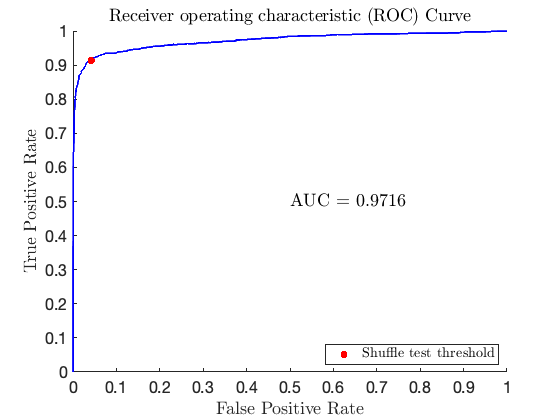

% Find the ROC data. (It can be found using Matlab built-in functions.
% However, just for the reader knowledge and for clearity show the detailed
% steps in the following)
thspan = linspace(min(C(:)),max(C(:)), N^2); %threshold span
ROC = [];
for i=1:length(thspan)
    B = C>=thspan(i); 
    FP = sum(and(~A(:),  B(:)));    % False Positive
    TP = sum(and( A(:),  B(:)));    % True Positive
    FN = sum(and( A(:), ~B(:)));    % False Negative
    TN = sum(and(~A(:), ~B(:)));    % True Negative
    
    FPR = FP/(FP+TN);   % False Positive Rate
    TPR = TP/(TP+FN);   % True Positive Rate 

    ROC = cat(1,ROC,[FPR,TPR]); %Store data in rows
end


% Find the operating point based on the estimated threshold
B = double(C>tol);
fp = sum(and(~A(:),  B(:))); tp = sum(and( A(:),  B(:)));
fn = sum(and( A(:), ~B(:))); tn = sum(and(~A(:), ~B(:)));
fpr = fp/(fp + tn);
tpr = tp/(tp + fn);

% Find the AUC and optimal operating point
[~,~,~,auc] = perfcurve(double(A(:)),C(:),1);

figure;
plot(ROC(:,1),ROC(:,2),'-b','LineWidth',2)
hold on
p1 = plot(fpr,tpr,'.r','MarkerSize',18);
legend(p1,'Shuffle test threshold','interpreter', 'latex','Location','southeast')

box off
axis([0 1 0 1]);
xticks(0:0.1:1);
yticks(0:0.1:1);
xlabel('False Positive Rate','interpreter', 'latex')
ylabel('True Positive Rate','interpreter', 'latex')
title('Receiver operating characteristic (ROC) Curve','interpreter', 'latex')
set(gca,'FontSize',16)
text(0.5,0.5,['AUC = ' num2str(auc,'%.4f')],'interpreter', 'latex',"FontSize",18)
drawnow

## More Examples

In this section we show one simple example, to illustrate the flow of the code use. 

We repeat some of the code just to show the user all what he need in one continous flow:

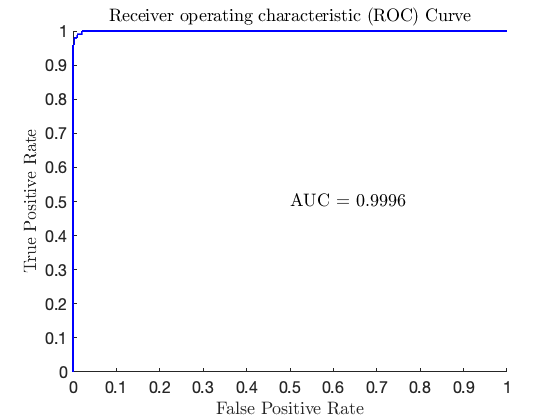

rng(1)
N = 20;        % Number of nodes
M = 1000;      % Sample size. 
% (increasing M may improve the result, but also increase the computation time)


A = double(rand(N)<0.25); % Coupling matrix, with probability 0.25. 
                          % This matrix can be anything you want
                          % If you have a matrix, just load it here and let
                          % N match your matrix size

% Kuramoto Critical Coupling (don't change this, read our paper)                          
K  = (2*sqrt(2*pi)/pi)*(1/eigs(double(A),1))*N;  


dt = 0.125; % Time step

Th0 = mod(2*pi*randn(N,1),2*pi);     %theta Initial condition
w   = mod(2*pi*randn(N,1),2*pi);     %natural frequency initial condition

dTheta = @(~,theta) w + (K/N)*sum(A.*sin(theta'-theta),2); % Kuramoto ODE model

[t,Th] = ode45(dTheta, 0:dt:M*dt, Th0); % Solving the forward model.

Thdot = (Th(2:end,:)-Th(1:end-1,:))./dt; % Forward difference.
Th(end,:) = [];

% End of parameters initialization and solving the forward model.

% Now we start the inverse problem and the coupling estimation with
% entropic regression:
C   = zeros(N);  % Initialize the matrix to store the relevence weight of each edge.
tol = zeros(N,1);% Initialize the vector to store the estimated tolerence.

parfor i=1:N
    [C(i,:), tol(i)] = erfit_Kuramoto(Thdot(:,i),Th, i);
end
% End of entropic regression.   

% Results:
B = double(C>tol);  %Result based on shuffle test 
[FPR,TPR,~,auc] = perfcurve(double(A(:)),C(:),1);

fig = figure;
plot(FPR,TPR,'-b','LineWidth',2)

box off
axis([0 1 0 1]);
xticks(0:0.1:1);
yticks(0:0.1:1);
xlabel('False Positive Rate','interpreter', 'latex')
ylabel('True Positive Rate','interpreter', 'latex')
title('Receiver operating characteristic (ROC) Curve','interpreter', 'latex')
set(gca,'FontSize',16)
text(0.5,0.5,['AUC = ' num2str(auc,'%.4f')],'interpreter', 'latex',"FontSize",18)
drawnow